# **Portfolio Analysis: Backtesting and Performance Evaluation **

# Self-Information Content Double-Sorts

### **Preliminaries**

clc;
clear;

### Data

opts = detectImportOptions('sample_buyback_portfolio_entropy.csv');
data = readtable('sample_buyback_portfolio_entropy.csv', opts);
data.si_mean = str2double(data.si_mean);
data.si_delta = str2double(data.si_delta);

#### Sorting variables

control_variable = 'numinstblockowners'

control_variable = 'numinstblockowners'

indicator_variable = 'entropy_I'

indicator_variable = 'entropy_I'

### Backtesting and Performance Evaluation

Function Inputs:

- Data

- Starting Year

- Ending Year

- Lookback Window Expressed in Months

- Control Variable

- Variable of Interest

- Rebalancing Frequency

#### 3x3 Double-Sort

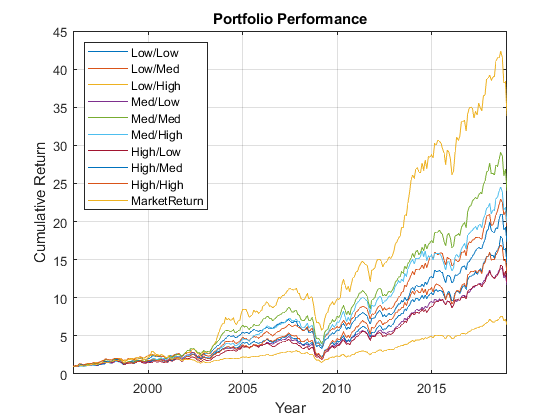

returns = 276×38 table
      Month      Time        P1            P2            P3            P4           P5            P6            P7           P8            P9        Excess_P1     Excess_P2     Excess_P3     Excess_P4     Excess_P5    Excess_P6     Excess_P7     Excess_P8    Excess_P9     MarketReturn     MKTRF       SMB        HML        UMD        RMW        CMA         LIQ          Rf      Obs_P1    Obs_P2    Obs_P3    Obs_P4 

low_low = 7×4 table
                   Estimate        SE        tStat       pValue  
                   _________    ________    _______    __________

    (Intercept)    0.0033828    0.001349     2.5077       0.01274
    MKTRF            0.90396    0.036029     25.089    2.0795e-72
    SMB              0.55046    0.046641     11.802    3.4979e-26
    HML             0.099972    0.061419     1.6277       0.10476
    UMD             -0.19343    0.027315    -7.0815    1.2451e-11
    RMW              0.17237    0.065307     2.6394     0.0087899
    CMA              0.14978    0.083604     1.7916      0.074321


low_med = 7×4 table
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________

    (Intercept)    0.0043823    0.0013961      3.139      0.001884
    MKTRF            0.87307     0.037288     23.414    7.3256e-67
    SMB              0.44689      0.04827     9.2581    6.8176e-18
    HML             0.083331     0.063565      1.311       0.19099
    UMD              -0.2404      0.02827    -8.5039    1.2882e-15
    RMW              0.11122     0.067589     1.6455       0.10104
    CMA              0.21002     0.086525     2.4272      0.015871


low_high = 7×4 table
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________

    (Intercept)    0.0067198    0.0018471      3.638    0.00032936
    MKTRF            0.83579     0.049336     16.941     2.623e-44
    SMB              0.64957     0.063866     10.171    9.0049e-21
    HML              0.10568     0.084103     1.2566          0.21
    UMD             -0.11138     0.037403    -2.9778     0.0031675
    RMW              -0.1522     0.089426    -1.7019      0.089923
    CMA              0.33325      0.11448      2.911      0.003905


med_low = 7×4 table
                    Estimate        SE         tStat       pValue  
                   __________    _________    _______    __________

    (Intercept)    0.00042821    0.0012521    0.34199       0.73263
    MKTRF              1.0175     0.033443     30.426     4.471e-89
    SMB               0.59212     0.043293     13.677    1.0982e-32
    HML               0.13975      0.05701     2.4514      0.014867
    UMD              -0.19321     0.025354    -7.6202    4.3425e-13
    RMW               0.41302     0.060619     6.8133     6.233e-11
    CMA               0.13478     0.077602     1.7369      0.083556


med_med = 7×4 table
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________

    (Intercept)    0.0030311    0.0011784     2.5722      0.010642
    MKTRF             1.0132     0.031474     32.192    2.9689e-94
    SMB              0.64275     0.040744     15.775    3.8325e-40
    HML              0.18956     0.053654      3.533    0.00048343
    UMD             -0.22386     0.023862    -9.3816    2.8269e-18
    RMW               0.4101      0.05705     7.1884    6.4772e-12
    CMA              0.16214     0.073033       2.22       0.02725


med_high = 7×4 table
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________

    (Intercept)    0.0034517    0.0012464     2.7693      0.006008
    MKTRF            0.99016      0.03329     29.744     4.956e-87
    SMB              0.56908     0.043094     13.205     4.973e-31
    HML              0.22795     0.056749     4.0167    7.6622e-05
    UMD             -0.19278     0.025238    -7.6384    3.8677e-13
    RMW             0.079348     0.060342      1.315       0.18964
    CMA              0.24556     0.077247     3.1789      0.001651


high_low = 7×4 table
                   Estimate        SE         tStat        pValue  
                   _________    _________    ________    __________

    (Intercept)    0.0018354    0.0012568      1.4604       0.14535
    MKTRF             0.9599     0.033567      28.596    1.5513e-83
    SMB              0.68559     0.043454      15.777    3.7707e-40
    HML               0.3136     0.057222      5.4804    9.7593e-08
    UMD             -0.33848     0.025449       -13.3    2.3125e-31
    RMW              0.35016     0.060845      5.7549    2.3564e-08
    CMA            -0.023955     0.077891    -0.30755       0.75866


high_med = 7×4 table
                   Estimate        SE         tStat        pValue   
                   _________    _________    ________    ___________

    (Intercept)    0.0013297    0.0010579      1.2569        0.20989
    MKTRF            0.99264     0.028256       35.13    1.6777e-102
    SMB              0.80057     0.036578      21.886     1.1043e-61
    HML              0.32856     0.048168      6.8211     5.9508e-11
    UMD             -0.22301     0.021422      -10.41     1.5138e-21
    RMW               0.4075     0.051217      7.9563     4.9621e-14
    CMA            0.0032214     0.065567    0.049132        0.96085


high_high = 7×4 table
                    Estimate        SE         tStat       pValue  
                   __________    _________    _______    __________

    (Intercept)    0.00095759    0.0012544     0.7634       0.44589
    MKTRF               1.046     0.033503     31.221    1.9874e-91
    SMB               0.86866      0.04337     20.029    3.0102e-55
    HML                0.3923     0.057113     6.8688    4.4818e-11
    UMD               -0.2483       0.0254    -9.7755    1.6466e-19
    RMW               0.32346     0.060728     5.3263    2.1187e-07
    CMA               0.10101     0.077742     1.2993       0.19494


table = 3×3 cell array
    {7×4 table}    {7×4 table}    {7×4 table}
    {7×4 table}    {7×4 table}    {7×4 table}
    {7×4 table}    {7×4 table}    {7×4 table}


per_plot =   10×1 Line array:

  Line    (Low/Low)
  Line    (Low/Med)
  Line    (Low/High)
  Line    (Med/Low)
  Line    (Med/Med)
  Line    (Med/High)
  Line    (High/Low)
  Line    (High/Med)
  Line    (High/High)
  Line    (MarketReturn)


[returns,low_low,low_med,low_high,med_low,med_med,med_high,high_low,high_med,high_high,table,per_plot] =...
    portfolio_double_sort_3x3(data,1996,2018,36,control_variable,indicator_variable,1)

#### 2x4 Double-Sort

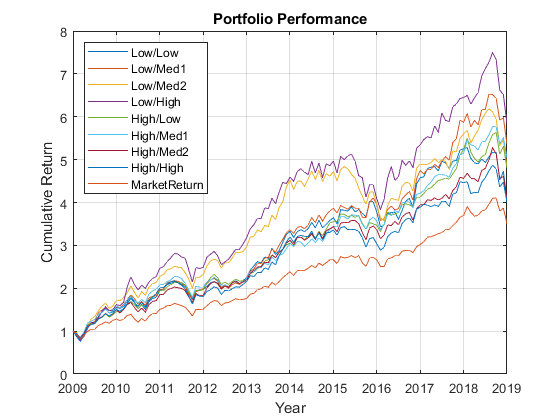

returns = 120×35 table
      Month      Time       P1           P2            P3           P4           P5           P6           P7           P8        Excess_P1    Excess_P2    Excess_P3     Excess_P4    Excess_P5    Excess_P6    Excess_P7    Excess_P8    MarketReturn     MKTRF       SMB        HML        UMD        RMW        CMA          LIQ          Rf      Obs_P1    Obs_P2    Obs_P3    Obs_P4    Obs_P5    Obs_P6    Obs_P7

low_low = 7×4 table
                    Estimate        SE         tStat       pValue  
                   __________    _________    _______    __________

    (Intercept)    0.00056332    0.0016672    0.33788       0.73608
    MKTRF              1.0951     0.045672     23.977    3.9069e-46
    SMB               0.53836     0.074473     7.2289    6.1598e-11
    HML               0.38453      0.08707     4.4164    2.3106e-05
    UMD              -0.21248     0.037877    -5.6097    1.4606e-07
    RMW               0.23456      0.11572     2.0271      0.045011
    CMA              -0.19265      0.13935    -1.3824       0.16956


low_med1 = 7×4 table
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________

    (Intercept)    0.0039945    0.0017651      2.263      0.025544
    MKTRF            0.93731     0.048354     19.384    9.9091e-38
    SMB              0.66659     0.078846     8.4543    1.1168e-13
    HML              0.20829     0.092182     2.2595       0.02577
    UMD             -0.20031     0.040101     -4.995    2.1613e-06
    RMW              0.17131      0.12251     1.3983       0.16476
    CMA             0.064269      0.14753    0.43563       0.66394


low_med2 = 7×4 table
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________

    (Intercept)    0.0027961    0.0017744     1.5758       0.11788
    MKTRF            0.96375     0.048609     19.827    1.3738e-38
    SMB              0.75927     0.079261     9.5794    2.8661e-16
    HML              0.15441     0.092668     1.6663      0.098433
    UMD             -0.30384     0.040312    -7.5371     1.292e-11
    RMW             0.074514      0.12315    0.60505       0.54636
    CMA               0.1049      0.14831    0.70731       0.48083


low_high = 7×4 table
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________

    (Intercept)    0.0046538    0.0024993      1.862      0.065196
    MKTRF            0.97425     0.068467      14.23    5.9664e-27
    SMB              0.81077      0.11164     7.2623    5.2067e-11
    HML              0.22727      0.13053     1.7412      0.084374
    UMD             -0.25313     0.056781    -4.4579    1.9607e-05
    RMW             0.070529      0.17347    0.40658       0.68508
    CMA              0.16825       0.2089    0.80543       0.42226


high_low = 7×4 table
                   Estimate        SE         tStat        pValue  
                   _________    _________    ________    __________

    (Intercept)    0.0022337    0.0015521      1.4392       0.15286
    MKTRF             0.9484     0.042518      22.306    3.3423e-43
    SMB              0.38496      0.06933      5.5526     1.889e-07
    HML            -0.027284     0.081057    -0.33661       0.73704
    UMD             -0.17847     0.035261     -5.0615    1.6285e-06
    RMW              0.42866      0.10772      3.9793    0.00012247
    CMA            -0.054944      0.12973    -0.42353       0.67271


high_med1 = 7×4 table
                   Estimate        SE         tStat        pValue  
                   _________    _________    ________    __________

    (Intercept)    0.0031166    0.0013554      2.2993      0.023326
    MKTRF            0.92275     0.037131      24.851     1.295e-47
    SMB               0.5658     0.060546       9.345    1.0007e-15
    HML            -0.044892     0.070787    -0.63418       0.52725
    UMD             -0.17834     0.030794     -5.7915    6.3822e-08
    RMW              0.16329     0.094076      1.7357      0.085334
    CMA             -0.13619      0.11329     -1.2021       0.23183


high_med2 = 7×4 table
                    Estimate        SE         tStat        pValue  
                   __________    _________    ________    __________

    (Intercept)    0.00073075    0.0010855      0.6732        0.5022
    MKTRF              1.0144     0.029736      34.112    2.5133e-61
    SMB               0.57559     0.048487      11.871    1.3589e-21
    HML             0.0047676     0.056689    0.084102       0.93312
    UMD              -0.11922     0.024661     -4.8345    4.2437e-06
    RMW               0.14371     0.075339      1.9075      0.058991
    CMA              -0.15289     0.090728     -1.6851      0.094722


high_high = 7×4 table
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________

    (Intercept)    0.0011105    0.0011266    0.98572       0.32638
    MKTRF            0.92855     0.030863     30.086    9.0414e-56
    SMB              0.76288     0.050324     15.159    5.3481e-29
    HML             0.030429     0.058837    0.51719       0.60604
    UMD             -0.15919     0.025595    -6.2196    8.6432e-09
    RMW              0.22773     0.078193     2.9124     0.0043231
    CMA              0.16984     0.094165     1.8036      0.073955


table = 2×4 cell array
    {7×4 table}    {7×4 table}    {7×4 table}    {7×4 table}
    {7×4 table}    {7×4 table}    {7×4 table}    {7×4 table}


per_plot =   9×1 Line array:

  Line    (Low/Low)
  Line    (Low/Med1)
  Line    (Low/Med2)
  Line    (Low/High)
  Line    (High/Low)
  Line    (High/Med1)
  Line    (High/Med2)
  Line    (High/High)
  Line    (MarketReturn)


%[returns,low_low,low_med1,low_med2,low_high,high_low,high_med1,high_med2,high_high,table,per_plot] =...
    %portfolio_double_sort_2x4(data,2009,2018,24,control_variable,indicator_variable,1)